Interface de texto para PVI

Autor:

  - Arménio Correia  .: armenioc@isec.pt

  - Ana Rita Conceição Pessoa - 2023112690 

  - João Francisco de Matos Claro - 2023112690 

Data : 13/03/2024

clear
strF="y+exp(3*t)";
%f=@(t,y) eval(vectorize(strF));
f=str2func(vectorize(strcat('@(t,y)', " ", strF)));
a = 0;
b = 1.5;
if ~(isscalar(b) && b > a)
    disp("Introduza um b > a");
end
n = 3;
if ~(isscalar(n) && n==floor(n) && n > 0)
    disp("Introduza um valor de n correto");
end
y0 = 2;

%Variables for ploting
h = (b-a)/n;
t = a:h:b;

yValue(:,1) = t.';
methods(1) = "t";


% Alinha automaticamente os graficos consoante o numero
% de metodos na figura
tiledlayout('flow');
%para mostrar o todos primeiro
if(true)
    [~, y]=NEuler(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    methods(end+1) = "Euler";
    % mostraAproximacoes("Euler", y);
    mostraGrafico("Euler", y, t);
end
if(true)
    [~, y]=NEulerMelhorado(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    methods(end+1) = "Euler M";
    % mostraAproximacoes("Euler Melhorado", y);
    mostraGrafico("Euler Melhorado", y, t);
end
if(true)
    [~, y]=RK2(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    methods(end+1) = "RK2";
    % mostraAproximacoes("RK2", y);
    mostraGrafico("RK2", y, t);
end
if(true)
    [~, y]=RK4(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    methods(end+1) = "RK4";
    % mostraAproximacoes("RK4", y);
    mostraGrafico("RK4", y, t);
end
if(false)
    [~, y]=AdamBashforth(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    methods(end+1) = "Adams-Bashforth";
    % mostraAproximacoes("Adams-Bashforth", y);
    mostraGrafico("Adams-Bashforth", y, t);
end
if(true)
    [~, y]=sExata(f,a,b,n,y0);
    
    yValue(:,length(yValue(1,:))+1) = y.';
    methods(end+1) = "Exata";
    % mostraAproximacoes("Exata", y);
    mostraGrafico("Exata", y, t);
end 
if(false)
    [tode, yode]=ode45(f, [a b], y0);

    %nao pode ser usada na funcao mostraGrafico
    %porque usa um t diferente das outras funcoes
    mostraAproximacoes("ode45", yode);
    mostraGrafico("ode45", yode, tode);
    fprintf('\nPontos de aproximação da ode45\n');
    disp(table(tode));
end

data = array2table(yValue, 'VariableNames',methods);
disp(data);

     t     Euler     Euler M     RK2       RK4      Exata 
    ___    ______    _______    ______    ______    ______

      0         2         2          2         2         2
    0.5       3.5      4.25     4.7454    4.4043    4.7139
      1    7.4908    10.799     14.413    12.348     14.12
    1.5    21.279    33.962     53.458     43.36    51.731



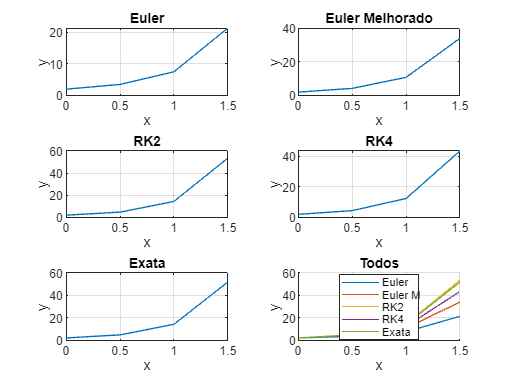


mostraTodos(methods, yValue); 

clf reset;

function mostraGrafico(metodo, y, t)   
    nexttile
    plot (t, y, 'DisplayName', metodo);
    title(metodo);
    xlabel('x');
    ylabel('y');
    grid on
end

function mostraTodos(metodo, y) 
% Desenha todos num unico grafico
    nexttile
    title("Todos");
    for i = 2:length(y)
        hold on
        plot (y(:,1).', y(:, i).', 'DisplayName', metodo(i));
        legend('location', 'best');
        xlabel('x');
        ylabel('y');
        hold off
        grid on
    end
end


function mostraAproximacoes(metodo, y)
   fprintf('\nAproximações obtidas ' + metodo + ":\n");
   disp(table(y));
end
